# Robotics I Mini-Project 4: Jacobian, Singularity

clearvars
cd('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject4')
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\MATLABrelated\'))
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject4'))
proj4init  % variables created from previous projects

## Part 1: Jacobian

Jacobian matrix maps changes in joint angles to the changes of its end effector. The end effector of a n-link robot arm can be discribed with two states: orientation and position. When use iterative method to reduce the error between current states and the desired states, we can provied numerical algorithm with the solution of the gradient - the Jacobian matrix. This improves the speed of the calculation.

#### a) Iterative Method

In the iterative method, the key is that the i th column of the Jacobian Matrix can be represented as the following:


$$(J_T)_0^{(i)} = \left[\matrix{(h_i)_0 \cr (h_i)_0^\times (p_{i,T})_0 }\right]$$


q=(rand(6,1)-.5)*pi;
irb1200.q=q;
% forward kinematics
%irb1200=fwddiffkiniter(irb1200);
irb1200=nlinkfwdkin(irb1200);
J=irb1200.J

J =          0    0.0174    0.0174    0.9940    0.0805    0.6941
         0    0.9998    0.9998   -0.0173    0.7861    0.3970
    1.0000         0         0    0.1084   -0.6128    0.6005
  -32.4534  234.5223  139.8525   -4.3811   58.6587    0.0000
   62.8272   -4.0848   -2.4359  -42.7730  -38.8452   -0.0000
         0  -62.2525 -500.1325   33.3450  -42.1213         0


To justify the resulting Jacobian, we compared our method with the MATLAB method. 

J1=geometricJacobian(irb1200_rbt,q,'body7')

J1 =    -0.0000    0.0174    0.0174    0.9940    0.0805    0.6941
   -0.0000    0.9998    0.9998   -0.0173    0.7861    0.3970
    1.0000   -0.0000   -0.0000    0.1084   -0.6128    0.6005
  -32.4534  234.5223  139.8525   -4.3811   58.6587    0.0000
   62.8272   -4.0848   -2.4359  -42.7730  -38.8452   -0.0000
         0  -62.2525 -500.1325   33.3450  -42.1213   -0.0000


diffJ1=(norm(J-J1))

diffJ1 = 1.0276e-13

The difference was small. 

#### b) Analytical Expression of $(J_4)_3(q)$

First of all we choose the 4th joint to compute the jacobian because origins of frame 4,5,6 are all located together. 

The difference to the previous question is that the i th column becomes:


$$(J_4)_3^{(i)} = \left[\matrix{(h_i)_3 \cr (h_i)_3^\times (p_{i,4})_3 }\right]$$


syms q1 q2 q3 q4 q5 q6 real
syms L1 L2 L3 L4 L5 positive
% P
p01=0*ex+L1*ez;p12=zz;p23=L2*ez;p34=L3*ez+L4*ex;p45=zz;p56=zz;p6T=L5*ex;
% H
h1=ez;h2=ey;h3=ey;h4=ex;h5=ey;h6=ex;
% q
q=[q1;q2;q3;q4;q5;q6];
% forward kinematics and Jacobian
irb1200_s.P=[p01 p12 p23 p34 p45 p56 p6T];
irb1200_s.H=[h1 h2 h3 h4 h5 h6];
irb1200_s.joint_type=[0 0 0 0 0 0];
irb1200_s.q=q;
irb1200_s=nlinkfwdkin(irb1200_s);
JT_0=irb1200_s.J;
R0T=simplify(irb1200_s.T(1:3,1:3));
R03=rot(h1,q1)*rot(h2,q2)*rot(h3,q3);
J4_3=simplify(phi(R03',-R0T*p6T)*JT_0)

$$J4\_3 = \left(\begin{array}{cccccc} -\sin\left(q_{2}+q_{3}\right) & 0 & 0 & 1 & 0 & \cos\left(q_{5}\right)\\ 0 & 1 & 1 & 0 & \cos\left(q_{4}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{2}+q_{3}\right) & 0 & 0 & 0 & \sin\left(q_{4}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & L_{3}+L_{2}\,\cos\left(q_{3}\right) & L_{3} & 0 & 0 & 0\\ L_{4}\,\cos\left(q_{2}+q_{3}\right)+L_{3}\,\sin\left(q_{2}+q_{3}\right)+L_{2}\,\sin\left(q_{2}\right) & 0 & 0 & 0 & 0 & 0\\ 0 & L_{2}\,\sin\left(q_{3}\right)-L_{4} & -L_{4} & 0 & 0 & 0 \end{array}\right)$$

The calculation of $(J_4)_3$ can be done directly with iteration, or, with Prof. Wen's method that transform $(J_T)_0$ calcuated from part a) using a transformation matrix where $(J_4)_3=(\phi_{4T})_{30} (J_T)_0\in \mathbb{R}^{6\times6}$.

Specifically:


$$(J_4)_3^{(i)}=\left[\matrix{ R_{30} & 0^{3\times3} \cr -R_{30}(p_{T6})_0^\times & R_{30}}\right]\cdot\left[\matrix{(h_i)_0 \cr (h_i)_0^\times (p_{i,T})_0 }\right] \\
\quad \quad \;= \left[\matrix{ R_{30}(h_i)_0 \cr R_{30}(h_i)_0^\times (p_{iT}-p_{T6})_0 }\right]\\
\quad \quad \;= \left[\matrix{ R_{30}(h_i)_0 \cr R_{30}(h_i)_0^\times (p_{iT}-p_{T6})_0 }\right]\\
\quad \quad \;= \left[\matrix{(h_i)_3 \cr (h_i)_3^\times (p_{i4})_3 }\right]

$$


note that $p_{T6} = p_{T4}$

Therefore, to recover $(J_T)_0$, we just reverse the steps above with $(J_T)_0=(\phi_{T4})_{03} (J_4)_3\in \mathbb{R}^{6\times6}$.

#### c) MATLAB $\text{geometricJacobian(robot,configuration,endeffectorname)}$

q=(rand(6,1)-.5)*pi;
J1=geometricJacobian(irb1200_rbt,q,'body7')

J1 =     0.0000   -0.6808   -0.6808    0.0006   -0.8244    0.4507
   -0.0000    0.7325    0.7325    0.0006    0.5661    0.6562
    1.0000         0         0   -1.0000   -0.0002   -0.6052
 -386.8276 -342.3911 -366.6579   53.7799  -28.0820    0.0000
  395.2346 -318.2561 -340.8122  -36.9301  -40.9155   -0.0000
         0 -552.8498 -106.0766    0.0117  -65.2788   -0.0000


% open defineRobot.m
irb1200_rbt

irb1200_rbt =   rigidBodyTree with properties:

     NumBodies: 7
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'body1'  'body2'  'body3'  'body4'  'body5'  'body6'  'body7'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'column'


The robot rigidBodyTree object was created using defineRobot.m in project4init.m. In this object, 'body7' is the name of the end effector, and q is randomly generated 6 by 1 angles.

#### d) Bonus Points

A. C. are both done as shown above. They were used to justify the calculation. 

B. In Prof. Wen's proj4JacobianComparison.m, function J4_3func(q) evaluate the analytical expression from part b).

irb1200.q=q;
irb1200=nlinkfwdkin(irb1200);

L2=448;L3=42;L4=451;

J4_3_num=[-sin(q(2) + q(3)),0, 0, 1, 0, cos(q(5));
    0, 1,   1, 0, cos(q(4)),  sin(q(4))*sin(q(5));
   cos(q(2) + q(3)), 0,   0, 0, sin(q(4)), -cos(q(4))*sin(q(5));
   0, L3 + L2*cos(q(3)),  L3, 0,       0, 0;
L4*cos(q(2) + q(3)) + L3*sin(q(2) + q(3)) + L2*sin(q(2)), 0, 0, 0,  0, 0;
   0, L2*sin(q(3)) - L4, -L4, 0, 0, 0];

After that we apply the transformation:

R03 = rot(irb1200.H(:,1),q(1))...
    *rot(irb1200.H(:,2),q(2))...
    *rot(irb1200.H(:,3),q(3));
% Now we need to bring p4T from T frame to 3 frame
R3T = rot(irb1200.H(:,4),q(4))...
    *rot(irb1200.H(:,5),q(5))...
    *rot(irb1200.H(:,6),q(6));
% we use phi.m 
JT_0_num = phi(R03,R3T*irb1200.P(:,end))* J4_3_num

JT_0_num =     0.0000    0.9819    0.9819    0.1064    0.6227    0.1064
   -0.0000    0.1896    0.1896   -0.5514    0.6858   -0.5514
    1.0000         0         0    0.8274    0.3769    0.8274
  110.5268  167.9560   88.0706         0   63.5679         0
   21.3380 -869.9815 -456.1900         0  -38.9585         0
         0 -112.5676 -264.5510         0  -34.1373         0


Next we use Prof. Wen's proj4JacobianComparison.m to generate 100 random joint angles to examine all three methods as well as their computation times. 

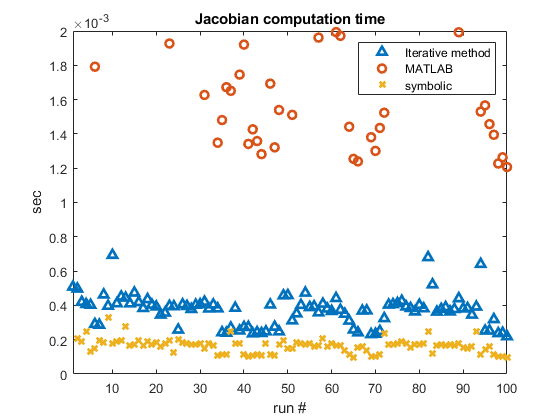

proj4JacobianComparison

Notice that there's a pretty clear difference between the computation time of the three methods. Symbolic Solution of the Jacobian resulted the least amount of computation time, with a disadvantage of generalization: It only works for joint configurations akin to IRB1200 arm. 

The Iterative method goes the second as its speed was bogged down by the lengthy trigonomitry evaluation toward the end of the arm. 

The Featherstone method used by MATLAB is slower than both the Iterative method, and has more variations of speed.

## Part 2: Singularities

#### a) Analytical expression and Geometric Interpretation

#### b) Draw Singular Pose for Each Type

We can write the Jacobian at the 4-th joint as:$(J_4)_3=\left[\matrix{ J_A & J_B \cr J_C & J_D}\right]$where because $J_D = 0^{3\times 3}$, to analyze singularities, we only need to look at $J_B $ and $J_D \in \mathbb{R}^{3\times3}$.

1. Wrist Singularities

 
$$J_B = \left[\matrix{h_4&h_5 & h_6}\right] = 
\left[\begin{array}{cccccc}
1 & 0 & \cos \left(q_5 \right)\\
0 & \cos \left(q_4 \right) & \sin \left(q_4 \right)\,\sin \left(q_5 \right)\\
 0 & \sin \left(q_4 \right) & -\cos \left(q_4 \right)\,\sin \left(q_5 \right)
\end{array}\right]$$


Analytically we can solve for the root of zero determinent:

JB = J4_3(1:3,4:6);
JB_det = simplify(det(JB))

$$JB\_det = -\sin\left(q_{5}\right)$$

we can see that when $q5 = \{-\pi,0,\pi\}$, $(J_4)_3$ will loss rank and the arm will reach a singularity configuration.

Geometrically, this means that $h_4$ and $h_6$ are colinear, pointing to the same direction or the opposite direction. 

JB_sing = subs(JB,q5,0)

$$JB\_sing = \left(\begin{array}{ccc} 1 & 0 & 1\\ 0 & \cos\left(q_{4}\right) & 0\\ 0 & \sin\left(q_{4}\right) & 0 \end{array}\right)$$

JB_self_motion_manifold = null(JB_sing)

$$JB\_self\_motion\_manifold = \left(\begin{array}{c} -1\\ 0\\ 1 \end{array}\right)$$

[image here]

2. Boundary Singularities


$$J_C = \left[\matrix{h_1 \times p_{14} & h_2 \times p_{24} & h_3 \times p_{34}}\right] \\
 \quad = \left[\matrix{h_1 \times p_{14} & h_2 \times p_{24} & h_2 \times p_{34}}\right] \\
\quad=\left[\begin{array}{ccc}
0 & L_3 +L_2 \,\cos \left(q_3 \right) & L_3 \\
L_4 \,\cos \left(q_2 +q_3 \right)+L_3 \,\sin \left(q_2 +q_3 \right)+L_2 \,\sin \left(q_2 \right) & 0 & 0\\
0 & L_2 \,\sin \left(q_3 \right)-L_4  & -L_4 
\end{array}\right]$$


JC = J4_3(4:6,1:3);
singJC = simplify(det(JC))

$$singJC = L_{2}\,\left(L_{4}\,\cos\left(q_{3}\right)+L_{3}\,\sin\left(q_{3}\right)\right)\,\left(L_{4}\,\cos\left(q_{2}+q_{3}\right)+L_{3}\,\sin\left(q_{2}+q_{3}\right)+L_{2}\,\sin\left(q_{2}\right)\right)$$

## Part 3

To solve for the inverse kinematics using Jacobian from the previous part, we can use gradient descent algorithm. 

#### a) N-link 3D inverse kinematics using iterative method

I used damped least square update with Frobenus norm of matrix square root of $E_R = RR^T_d
$, with $\dot{e_{R2}}=(2q_v)^T\omega$.

i) With #iteration = 100, step size of 0.4 we have the following results using Prof. Wen's checking function.

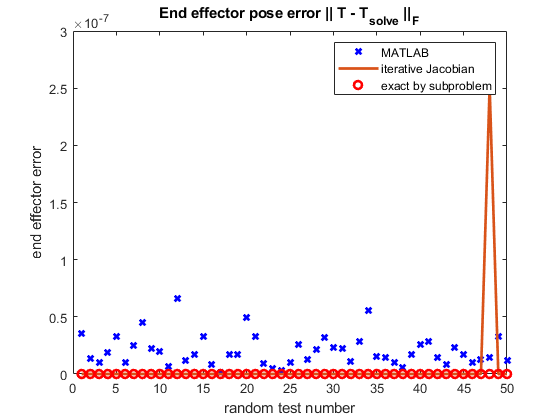

max MATLAB EE error: 6.60005e-08 
max subproblem EE error: 1.70828e-12 
max iterative EE error: 2.5146e-07 


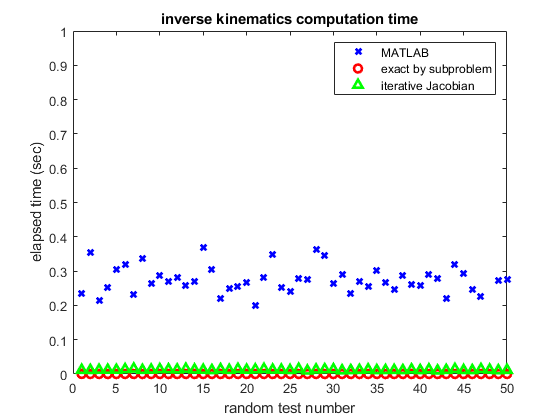

max and average MATLAB invkin computation time: 0.948007, 0.288666 
max and average subproblem invkin computation time: 9.51e-05, 3.61e-06 
max and average iterative invkin computation time: 0.0149396, 0.0119798 


proj4kincheck

 ii) A large step size makes the convergence faster, but might subject to outliers and diverge. Small step size gives slow converging speed, but is desirable towards the end of the convergence. Because the cost function is convex, global minimum is guaranteed; however, pairing the iteration number with the step size is important. With a desired error threshold, higher iteration number would help achieve the threshold, but computation time will increase at the same time. 

#### b) Compare the result with subproblem approach.

From the above two graphes, we can see that the subproblem approach wins over both speed and accuracy. This is due to the fact that geometric solutions once established, perform the calculation only once with the exact result determined. However, this is only achievable with at most 6 DoF arm. 

## Part 4: Jacobian and Trajectory Motion

Now we will be analyzing the near singularity motions of the s-path tracing from mini project 3.

#### a) Analyzing minimum SVD of the jacobian

First we reproduce the result from project 3:

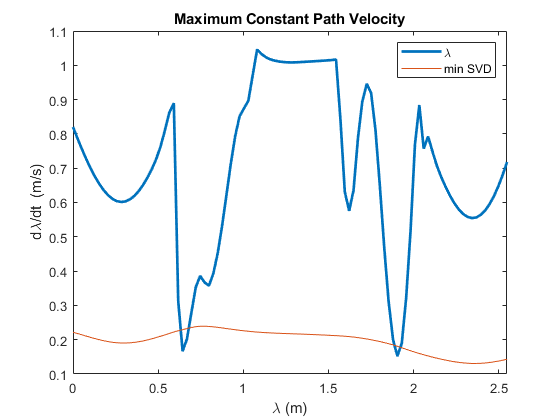

proj4init2
ldot = zeros(8,100);
J_trace = zeros(6,6,101);
svd_J = -1*ones(1,101);
sol = 6;
q = zeros(6,101);
for i = 1:101
    irb1200.T=[[xT(:,i) yT(:,i) zT(:,i)] pS(:,i);[0 0 0 1]];
    qsolns=invkinABB(irb1200); % output eight solutions
    q(:,i) = qsolns(sol,:)';
    %  Jacobian
    irb1200.q=q(:,i);
    irb1200=nlinkfwdkin(irb1200);
    J_trace(:,:,i) = irb1200.J;
    svd_J(i) = min(svd(irb1200.J));
end
dqdl = max(abs(diff(q')'))./diff(l')';
ldot(sol,:) = 2./dqdl;

figure;plot(l(1:end-1),ldot(pose,:),'linewidth',2);
hold on;
plot(l(1:end-1),svd_J(1:end-1));
hold off
xlabel('\lambda (m)')
ylabel('d\lambda/dt  (m/s)')
xlim([0,l(end-1)])
title('Maximum Constant Path Velocity')
legend('\lambda','min SVD')